% AE6511 Final Problem 6
% Tomoki Koike 
clear all; close all; clc;  % housekeeping commands
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

% BVP4C
x0 = [0.1361 0.8693 0.5797 0.5499 0.1450 0.8530 0.6221 0.3510 0.5132]

x0 =     0.1361    0.8693    0.5797    0.5499    0.1450    0.8530    0.6221    0.3510    0.5132


% x0 = rand(1,9);
mesh = linspace(0, 1, 10);
solinit = bvpinit(mesh, x0);
opts = bvpset('RelTol',1e-5, 'AbsTol',1e-6,'Stats','on','Nmax',10000);
sol = bvp4c(@odefcn,@bcfcn,solinit, opts);

The solution was obtained on a mesh of 730 points.
The maximum residual is  2.766e-08. 
There were 34257 calls to the ODE function. 
There were 431 calls to the BC function. 


% Unpack results
T = linspace(0,1,1000);
[xopt,xdopt] = deval(sol,T);
xopt = xopt.'; xdopt = xdopt.';
tf_eval = mean(xopt(1,9));
tf_out = abs(tf_eval);
tspan = tf_out * T;

x1_sol = xopt(:,1);
x2_sol = xopt(:,2);
x3_sol = xopt(:,3);
x4_sol = xopt(:,4);
lambda1_sol = xopt(:,5);
lambda2_sol = xopt(:,6);
lambda3_sol = xopt(:,7);
lambda4_sol = xopt(:,8);

u1 = -lambda2_sol;
u2 = -lambda4_sol;

H = (0.5*(u1.^2 + u2.^2) + lambda1_sol.*xdopt(:,1)/tf_eval ...
    + lambda2_sol.*xdopt(:,2)/tf_eval ...
    + lambda3_sol.*xdopt(:,3)/tf_eval ...
    + lambda4_sol.*xdopt(:,4)/tf_eval);
H = round(H,4);

% J = 0.5*(x2_sol(end)-2)^2 + 0.5*(trapz(u1.^2) + trapz(u2.^2));

% Compute the controls (linear) from data
b1 = u1(1);
a1 = (u1(end)-b1) / tf_out;
b2 = u2(1);
a2 = (u2(end)-b2) / tf_out;
f = @(t) 0.5*((a1*t + b1).^2 + (a2*t + b2).^2);

% The minimized objective
J_min = 0.5*(x2_sol(end)-2)^2 + integral(f,0,tf_out)

J_min = 0.9945

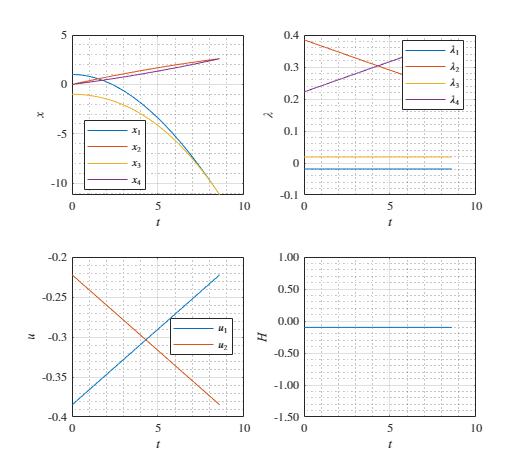

fig = figure("Renderer","painters","Position",[60 60 900 800]);
    % x vs t
    subplot(2,2,1)
    plot(tspan, x1_sol,'DisplayName','$x_1$')
    hold on;
    plot(tspan, x2_sol,'DisplayName','$x_2$')
    plot(tspan, x3_sol,'DisplayName','$x_3$')
    plot(tspan, x4_sol,'DisplayName','$x_4$')
    xlabel('$t$')
    ylabel('$x$')
    grid on; grid minor; box on; hold off; legend('Location','best');
    % lambda vs t
    subplot(2,2,2)
    plot(tspan, lambda1_sol,'DisplayName','$\lambda_1$')
    hold on;
    plot(tspan, lambda2_sol,'DisplayName','$\lambda_2$')
    plot(tspan, lambda3_sol,'DisplayName','$\lambda_3$')
    plot(tspan, lambda4_sol,'DisplayName','$\lambda_4$')
    xlabel('$t$')
    ylabel('$\lambda$')
    grid on; grid minor; box on; hold off; legend('Location','best');
    % u vs t
    subplot(2,2,3)
    plot(tspan, u1,'DisplayName','$u_1$')
    hold on;
    plot(tspan, u2,'DisplayName','$u_2$')
    xlabel('$t$')
    ylabel('$u$')
    grid on; grid minor; box on; hold off; legend('Location','best');
    % Hamiltonian 
    subplot(2,2,4)
    plot(tspan, H)
    xlabel('$t$')
    ylabel('$H$')
    ytickformat('%,.2f')
    grid on; grid minor; box on;
saveas(fig, 'outputs/p6_result.png');

## Function

function dxdt = odefcn(t,x)
    dxdt = zeros(9,1); 
    dxdt(1) = x(2); % x1
    dxdt(2) = -x(6); % x2
    dxdt(3) = x(4); % x3
    dxdt(4) = -x(8); % x4
    dxdt(5) = 0;  % lambda1
    dxdt(6) = -x(5);  % lambda2
    dxdt(7) = 0;  % lambda3
    dxdt(8) = -x(7);  % lambda4
    dxdt(9) = 0; % tf
    dxdt = dxdt * x(9);
end

function res = bcfcn(xa,xb)
    res = zeros(9,1);
    res(1) = xa(1) - 1;  % x1(0)
    res(2) = xa(2);  % x2(0)
    res(3) = xa(3) + 1;  % x3(0)
    res(4) = xa(4);  % x4(0)
    res(5) = xb(1) - xb(3);  % x1(tf) - x3(tf)
    res(6) = xb(2) - xb(4);  % x2(tf) - x4(tf)
    res(7) = xb(5) + xb(7);  % lambda1(tf) + lambda3(tf)
    res(8) = xb(6) + xb(8) - xb(2) + 2;  % lambda2(tf) + lambda4(tf) - x2(tf) + 2
    res(9) = (-0.5*(xb(6)^2 + xb(8)^2) + xb(5)*xb(2) - xb(6)*xb(6) + ...
        xb(7)*xb(4) - xb(8)*-xb(8)) * xb(9); % H(t_f)
end
